## **Numerical Methods**

**Chapter**     2

**Exercise**    1

**Author**       Supakorn Suttiruang (Lum)

**Date**           9 September 2019

clear
clc

Find the first positive root of $\mathrm{cosh}\left(x\right)\mathrm{cos}\left(x\right)+1=0$

% Function definition
f = @(x)((cosh(x).*cos(x)) + 1);

(a) Using the graphical method

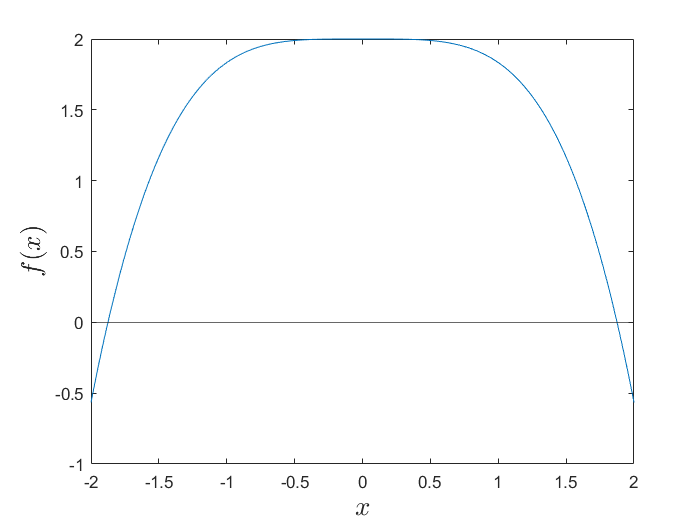

X = -2:0.01:2;
plot(X, f(X));
yline(0);
xlabel('$x$', "Interpreter", "latex", "FontSize", 16);
ylabel('$f(x)$', "Interpreter", "latex", "FontSize", 16);

The first positive root of the fuction occurs at $x\approx 1\ldotp 88$

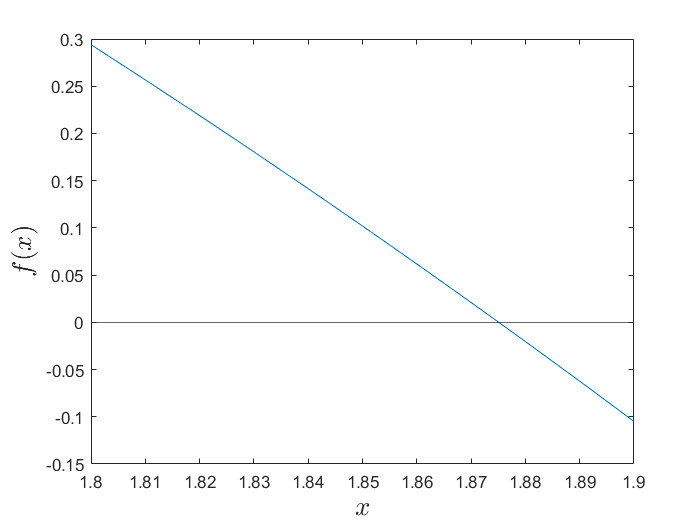

X = 1.8:0.01:1.9;
plot(X, f(X));
yline(0);
xlabel('$x$', "Interpreter", "latex", "FontSize", 16);
ylabel('$f(x)$', "Interpreter", "latex", "FontSize", 16);

(b) Using the bisection method

From the graphical method, we know that the first positive root is definitely between $x_L =1\ldotp 87$ and $x_R =1\ldotp 88$ so this is going to be the left and right boundary for our bisection method

x_L = 1.87;
x_R = 1.88;
x_M = (x_L + x_R) / 2;
epsilon = 1e-7;
iter_count = 0;

while (abs(f(x_M)) > epsilon)
    iter_count = iter_count + 1;
    if f(x_M)*f(x_R) > 0
        % x_M is on the positive side and is now the new x_R
        x_R = x_M;
    else
        % x_M is on the negative side and is now the new x_L
        x_L = x_M;
    end
    x_M = (x_L + x_R) / 2;
end

The root of the solution $\bar{x}$ is

disp(x_M);

   1.875104064941406




$$f\left(\bar{x} \right)=$$


disp(f(x_M));

     1.560306106540565e-08



Completed in

disp(iter_count)

    14



iterations

(c) Using the false-position method